## A03 - Generation

clear all;
close all;
clc;
rng(0);

We have to start from the distribution fitted in the **A02**, so let's recall the parameters achieved for $p, \lambda_1$ and $\lambda_2$.

**Method of moments fit**


$$p = 0.4999 \\
\lambda_1 = 0.0043 \\
\lambda_2 = 0.0043$$


**Maximum likelihood fit**


$$p = 0.6438 \\
\lambda_1 = 0.0035 \\
\lambda_2 = 0.0092$$


### 1. Generate 80 samples from an Hyper-Exp distribution with the parameters obtained from the fitting procedure

The Hyper-Exp distribution is generated as:


$$if u_1 < p_1 \rightarrow -\frac{ln(u_2)}{\lambda_1} \\
if u_1 > p_1 \rightarrow -\frac{ln(u_2)}{\lambda_2} \\
$$


where:


$$p_1 = p \in [0,1] \\
u_1, u_2 \sim U(0,1)$$


#### 1.1 Maximum likelihood parameters

n = 80;
gen_data_ml = zeros(1,n);

p1 = 0.6438;
l1 = 0.0035;
l2 = 0.0092;

% Note that we call rand 3 times but since only one of the two branches is
% executed, actually we are calling rand only 2 times.
for i = 1:80
    if rand <= p1
        gen_data_ml(i) = -log(rand)/l1;
    else
        gen_data_ml(i) = -log(rand)/l2;
    end
end
gen_data_ml

gen_data_ml =    10.7550   25.8879  664.9967  172.4352    3.8851    8.5281   78.5687  212.2531   25.1508    4.4947  362.2041    7.4224   30.1538  101.7298  191.8479  374.7018  878.6843   55.4980  124.8413  366.1261  275.2832   24.9089  203.9517  124.7061   30.5927  110.3142  197.4337  198.9784  117.1387  427.6998  148.4912  102.2842    4.5174  564.5677  387.6296  148.8381  153.5365  114.1161  394.8481  213.7284   52.9519  170.9542  136.1224   30.7307  161.6994  834.1987   71.2942  221.8416  216.0914  310.6596


#### 1.2 Method of moments parameters

n = 80;
gen_data_mm = zeros(1,n);

p1 = 0.4999;
l1 = 0.0043;
l2 = 0.0043;

% Note that we call rand 3 times but since only one of the two branches is
% executed, actually we are calling rand only 2 times.
for i = 1:80
    if rand <= p1
        gen_data_mm(i) = -log(rand)/l1;
    else
        gen_data_mm(i) = -log(rand)/l2;
    end
end
gen_data_mm

gen_data_mm =   219.1345  210.8274  470.9664   10.4318  655.1376  242.0554  970.5034  413.4687   72.6405  185.2226  282.8634  387.4991  394.2976  109.0731  584.1290   59.0635  193.1250  275.1230  156.2402   53.4012  225.8722  146.4096   14.6368  138.9658  123.8731  279.0295  341.2920  380.4570  411.1164  193.2103   18.5383  392.6495    4.7580  510.9655  208.0757  311.3030   79.2510  498.1437  265.8743  157.5704  311.0632  821.6029   73.0832  127.2729  181.1708  140.3864  340.1786  109.6532  215.7130    2.8118


### 2. Compare, with the Q-Q plot, the samples generated with the ones used to perform the fit

Let's load the data

T = readtable('../A02/data.xlsx');
T.Properties.VariableNames = {'data'};
data = T.data

data = 	1.0e+03 *

    0.0831
    0.0956
    0.1975
    0.0962
    0.4626
    0.0375
    0.4831
    0.1537
    0.0000
    0.0565


Recalling that $F(t) = 1-p_1e^{-\lambda_1 t} - (1-p_1)e^{-\lambda_2 t}$

t = 1/n:1/n:1;

F = @(t, p1, l1, l2) 1-p1*exp(-t*l1)-(1-p1)*exp(-t*l2)

F = function_handle with value:
    @(t,p1,l1,l2)1-p1*exp(-t*l1)-(1-p1)*exp(-t*l2)


p1 = 0.6438;
l1 = 0.0035;
l2 = 0.0092;
F_from_gen_ml = F(sort(gen_data_ml), p1, l1, l2)

F_from_gen_ml =     0.0061    0.0212    0.0245    0.0246    0.0334    0.0400    0.0458    0.0573    0.0591    0.0803    0.1267    0.1278    0.1313    0.1313    0.1352    0.1505    0.1508    0.1528    0.1534    0.1570    0.2410    0.2463    0.2530    0.2561    0.2703    0.2867    0.2942    0.3135    0.3189    0.3381    0.4093    0.4109    0.4333    0.4435    0.4515    0.4622    0.4708    0.4711    0.4984    0.5186    0.5263    0.5270    0.5371    0.5540    0.5722    0.5750    0.5931    0.6079    0.6101    0.6195


p1 = 0.4999;
l1 = 0.0043;
l2 = 0.0043;
F_from_gen_mm = F(sort(gen_data_mm), p1, l1, l2)

F_from_gen_mm =     0.0120    0.0203    0.0439    0.0610    0.0766    0.0963    0.1148    0.1406    0.1747    0.1825    0.2038    0.2052    0.2209    0.2243    0.2559    0.2683    0.2697    0.2788    0.2873    0.2888    0.3180    0.3203    0.3462    0.3510    0.3744    0.3759    0.3901    0.4130    0.4215    0.4233    0.4498    0.4532    0.4672    0.4814    0.4892    0.4921    0.5201    0.5289    0.5412    0.5462    0.5491    0.5641    0.5643    0.5913    0.5961    0.6045    0.6103    0.6214    0.6468    0.6658


#### 2.1 Maximum likelihood parameters vs. sampled data

Let's create the Q-Q plot for the generated data based on ML parameters vs. sampled data

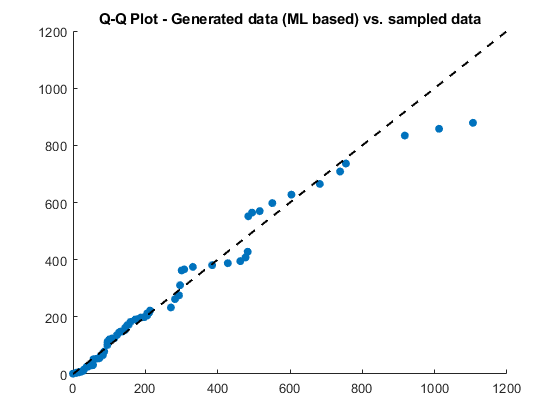

figure();
s1 = scatter(sort(data), sort(gen_data_ml));
s1.Marker = 'o';
s1.MarkerFaceColor = 'flat';
s1.MarkerEdgeColor = 'none';

hline = refline([1,0]);
hline.Color = 'k';
hline.LineStyle = '--';
hline.LineWidth = 1.5;

hold off;
title('Q-Q Plot - Generated data (ML based) vs. sampled data');

#### 2.2 Method of moments parameters vs. sampled data

Let's create the Q-Q plot for the generated data based on MM parameters vs. sampled data

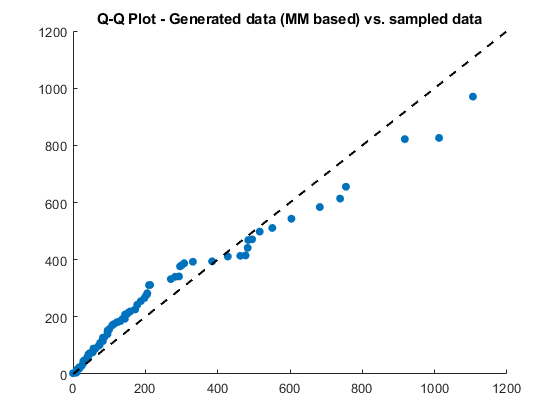

figure();
s1 = scatter(sort(data), sort(gen_data_mm));
s1.Marker = 'o';
s1.MarkerFaceColor = 'flat';
s1.MarkerEdgeColor = 'none';

hline = refline([1,0]);
hline.Color = 'k';
hline.LineStyle = '--';
hline.LineWidth = 1.5;

hold off;
title('Q-Q Plot - Generated data (MM based) vs. sampled data');

#### 2.3 Compare MM & ML generations

Let's create the P-P plot for the generated data based on ML parameters

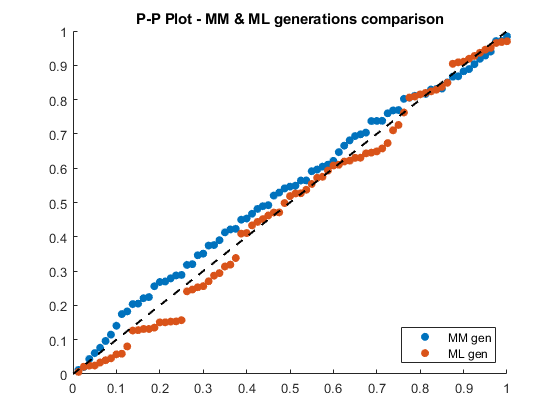

figure();
s1 = scatter(t, F_from_gen_mm);
s1.Marker = 'o';
s1.MarkerFaceColor = 'flat';
s1.MarkerEdgeColor = 'none';
hold on;
s2 = scatter(t, F_from_gen_ml);
s2.Marker = 'o';
s2.MarkerFaceColor = 'flat';
s2.MarkerEdgeColor = 'none';

hline = refline([1,0]);
hline.Color = 'k';
hline.LineStyle = '--';
hline.LineWidth = 1.5;

hold off;
legend({'MM gen', 'ML gen'}, 'Location', 'southeast');
title('P-P Plot - MM & ML generations comparison');